clear;
close all;

excludeSubjects();

ans =   Map with properties:

        Count: 45
      KeyType: char
    ValueType: any


%add nice things to path
addpath('D:\Documents\software\cbrewer') %for color
[cb] = cbrewer('qual','Set1',10,'pchip');

N=length(subjects)

N = 49

[ACGroup, CCGroup,CAGroup, AAGroup] = deal([]);
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);
[TTGroup, TVGroup, VTGroup, VVGroup] = deal([]);
[nR_S1,nR_S2,nR_signal_nR_noise, nR_tilted, nR_vertical] = deal([]);


for s=which_subjects
        
    subject = data_struct(participants.name_initials{s});
    

        %break into taskXresponseXsignal
        DisCC = reshape(histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1 & subject.DisInclude==1),1:6),6,1);
        DisCA = reshape(histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0 & subject.DisInclude==1),1:6),6,1);
        DisAC = reshape(histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1 & subject.DisInclude==1),1:6),6,1);
        DisAA = reshape(histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0 & subject.DisInclude==1),1:6),6,1);
        
        DetSignalYes = reshape(histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1 & subject.DetInclude==1),1:6),6,1);
        DetSignalNo = reshape(histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0 & subject.DetInclude==1),1:6),6,1);
        DetNoiseYes = reshape(histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1 & subject.DetInclude==1),1:6),6,1);
        DetNoiseNo = reshape(histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0 & subject.DetInclude==1),1:6),6,1);
        
        TiltTT = reshape(histc(subject.TiltConf(subject.TiltSignal==1 & subject.TiltResp==1 & subject.TiltInclude==1),1:6),6,1);
        TiltTV = reshape(histc(subject.TiltConf(subject.TiltSignal==1 & subject.TiltResp==0 & subject.TiltInclude==1),1:6),6,1);
        TiltVT = reshape(histc(subject.TiltConf(subject.TiltSignal==0 & subject.TiltResp==1 & subject.TiltInclude==1),1:6),6,1);
        TiltVV = reshape(histc(subject.TiltConf(subject.TiltSignal==0 & subject.TiltResp==0 & subject.TiltInclude==1),1:6),6,1);
        
        nR_S1(s,:) = [reshape(DisAA(end:-1:1),1,[]) reshape(DisAC,1,[])];
        nR_S2(s,:) = [reshape(DisCA(end:-1:1),1,[]) reshape(DisCC,1,[])];
        nR_signal(s,:) = [reshape(DetSignalNo(end:-1:1),1,[]) reshape(DetSignalYes,1,[])];
        nR_noise(s,:) = [reshape(DetNoiseNo(end:-1:1),1,[]) reshape(DetNoiseYes,1,[])];
        nR_tilted(s,:) = [reshape(TiltTV(end:-1:1),1,[]) reshape(TiltTT,1,[])];
        nR_vertical(s,:) = [reshape(TiltVV(end:-1:1),1,[]) reshape(TiltVT,1,[])];
end

## zROC

To compare type-I and type-II sensitivity between tasks and responses I plot the zROC curve for each task and subject. 

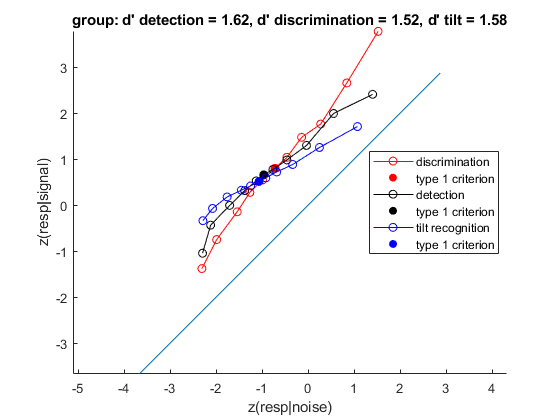

zDisS1G = [];
zDisS2G = [];
zDetSignalG = [];
zDetNoiseG = [];
zTiltTG = [];
zTiltVG = [];

DetSlopes = nan(N,1);
DisSlopes = nan(N,1);
TiltSlopes = nan(N,1);

DetR2 = nan(N,1);
DisR2 = nan(N,1);
TiltR2 = nan(N,1);

for s=which_subjects
        
    %create response count vectors, compute response probabilities 
    % and extract corresponding Z values
    DetSignalResponseCount = nR_signal(s,:);
    pDetSignal = DetSignalResponseCount/sum(DetSignalResponseCount);
    zDetSignal = norminv(cumsum(pDetSignal(end:-1:2)));
    
    DetNoiseResponseCount = nR_noise(s,:);
    pDetNoise = DetNoiseResponseCount/sum(DetNoiseResponseCount);
    zDetNoise = norminv(cumsum(pDetNoise(end:-1:2)));
    
    DisS1ResponseCount = nR_S1(s,:);
    pDisS1 = DisS1ResponseCount/sum(DisS1ResponseCount);
    zDisS1 = norminv(cumsum(pDisS1(end:-1:2)));
    
    DisS2ResponseCount = nR_S2(s,:);
    pDisS2 = DisS2ResponseCount/sum(DisS2ResponseCount);
    zDisS2 = norminv(cumsum(pDisS2(end:-1:2)));
    
    TiltTResponseCount = nR_tilted(s,:);
    pTiltT = TiltTResponseCount/sum(TiltTResponseCount);
    zTiltT = norminv(cumsum(pTiltT(end:-1:2)));
    
    TiltVResponseCount = nR_vertical(s,:);
    pTiltV = TiltVResponseCount/sum(TiltVResponseCount);
    zTiltV = norminv(cumsum(pTiltV(end:-1:2)));
    
    %plot
    figure;
    hold on;
    axis equal
    plot(zDisS1,zDisS2,'-or')
    scatter(zDisS1(6), zDisS2(6), 'red','filled')
    plot(zDetNoise, zDetSignal, '-ok')
    scatter(zDetNoise(6), zDetSignal(6),'black','filled')
    plot(zTiltV, zTiltT, '-ob')
    scatter(zTiltV(6), zTiltT(6),'blue','filled')
    refline(1,0)    
    xlabel('z(resp|noise)');
    ylabel('z(resp|signal)');
    title(sprintf('%d: d detection = %.2f, d discrimination = %.2f, d tilt = %.2f', ...
       s, zDetSignal(6)-zDetNoise(6), zDisS2(6)-zDisS1(6),zTiltT(6)-zTiltV(6)));
    if s==1
        legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion','Location','best')
    end
    
    zDisS1G = [zDisS1G; zDisS1];
    zDisS2G = [zDisS2G; zDisS2];
    zDetSignalG = [zDetSignalG; zDetSignal];
    zDetNoiseG = [zDetNoiseG; zDetNoise];
    zTiltTG = [zTiltTG; zTiltT];
    zTiltVG = [zTiltVG; zTiltV];
    
    % sometimes, due to a floating point error, the sum of all
    % probabilities is a bit lower than 1, and then the inverse normal
    % cumulative of this number is not inf, but a number like 8.
    % Theoretically, the highest number that is not infinity that we should
    % expect is abs(norminv(1/(25*5))=2.4089. So we ignore all numbers
    % higher than 3 in absolute value, as they refelct a floating point
    % error.
    
    robustDetBins = find(abs(zDetNoise)<3 & abs(zDetSignal)<3);
    [DetCoefs1,DetS1] = polyfit(zDetNoise(robustDetBins),zDetSignal(robustDetBins),1);
    [DetCoefs2,DetS2] = polyfit(zDetSignal(robustDetBins),zDetNoise(robustDetBins),1);

    DetSlopes(s) = mean([DetCoefs1(1),1/DetCoefs2(1)]);
    %from here: https://uk.mathworks.com/matlabcentral/answers/159369-polyfit-and-r-2-value
    DetR2(s) = 1 - (DetS1.normr/norm(zDetSignal(robustDetBins) - mean(zDetSignal(robustDetBins))))^2;

    robustDisBins = find(abs(zDisS1)<3 & abs(zDisS2)<3);
    [DisCoefs1,DisS1] = polyfit(zDisS1(robustDisBins),zDisS2(robustDisBins),1);
    [DisCoefs2,DisS2] = polyfit(zDisS2(robustDisBins),zDisS1(robustDisBins),1);
    
    DisSlopes(s) = mean([DisCoefs1(1),1/DisCoefs2(1)]);
    
    %from here: https://uk.mathworks.com/matlabcentral/answers/159369-polyfit-and-r-2-value
    DisR2(s) = 1 - (DisS1.normr/norm(zDisS1(robustDisBins) - mean(zDisS2(robustDisBins))))^2;
    
    robustTiltBins = find(abs(zTiltT)<3 &abs(zTiltV)<3);
    [TiltCoefs1,TiltS1] = polyfit(zTiltV(robustTiltBins),zTiltT(robustTiltBins),1);
    [TiltCoefs2,TiltS2] = polyfit(zTiltT(robustTiltBins),zTiltV(robustTiltBins),1);
    TiltSlopes(s) = mean([TiltCoefs1(1),1/TiltCoefs2(1)]);
    %from here: https://uk.mathworks.com/matlabcentral/answers/159369-polyfit-and-r-2-value
    TiltR2(s) = 1 - (TiltS1.normr/norm(zTiltV(robustTiltBins) - mean(zTiltT(robustTiltBins))))^2;
end

% [h,sig,ci,stats]=ttest(log2(DisSlopes))
% [h,sig,ci,stats]=ttest(log2(DetSlopes))
% [h,sig,ci,stats]=ttest(log2(TiltSlopes))


zDisS1G(~isfinite(zDisS1G)) = 2.5*sign(zDisS1G(~isfinite(zDisS1G)));
zDisS2G(~isfinite(zDisS2G)) = 2.5*sign(zDisS2G(~isfinite(zDisS2G)));

zDetSignalG(~isfinite(zDetSignalG)) = 2.5*sign(zDetSignalG(~isfinite(zDetSignalG)));
zDetNoiseG(~isfinite(zDetNoiseG)) = 2.5*sign(zDetNoiseG(~isfinite(zDetNoiseG)));

zTiltTG(~isfinite(zTiltTG)) = 2.5*sign(zTiltTG(~isfinite(zTiltTG)));
zTiltVG(~isfinite(zTiltVG)) = 2.5*sign(zTiltVG(~isfinite(zTiltVG)));
%plot
    figure;
    hold on;
    axis equal
    plot(nanmean(zDisS1G),nanmean(zDisS2G),'-or')
    scatter(nanmean(zDisS1G(:,6)), nanmean(zDisS2G(:,6)), 'red','filled')
    plot(nanmean(zDetNoiseG), nanmean(zDetSignalG), '-ok')
    scatter(nanmean(zDetNoiseG(:,6)), nanmean(zDetSignalG(:,6)),'black','filled')
    plot(nanmean(zTiltVG), nanmean(zTiltTG), '-ob')
    scatter(nanmean(zTiltVG(:,6)), nanmean(zTiltTG(:,6)),'blue','filled')
    refline(1,0)    
    xlabel('z(resp|noise)');
    ylabel('z(resp|signal)');
    title(sprintf('group: d'' detection = %.2f, d'' discrimination = %.2f, d'' tilt = %.2f', ...
       nanmean(zDetSignalG(:,6))-nanmean(zDetNoiseG(:,6)), nanmean(zDisS2G(:,6))-nanmean(zDisS1G(:,6)),...
       nanmean(zTiltTG(:,6))-nanmean(zTiltVG(:,6))));
        legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion','tilt recognition', 'type 1 criterion','Location','best')


save(fullfile('..','analyzed','slopes.mat'),'DisSlopes','DetSlopes','TiltSlopes')


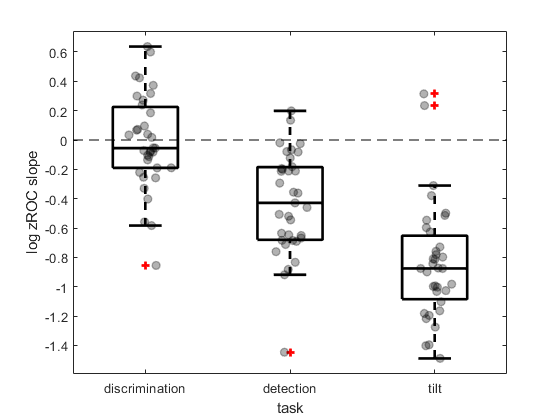

noise1 = normrnd(0,0.05,1,N);
noise2 = normrnd(0,0.05,1,N);
noise3 = normrnd(0,0.05,1,N);

figure; hold on;
h=boxplot([log2(DisSlopes) log2(DetSlopes) log2(TiltSlopes)],'Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(ones(N,1)+noise1',log2(DisSlopes),'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(N,1)+noise2',log2(DetSlopes),'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(3*ones(N,1)+noise2',log2(TiltSlopes),[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('log zROC slope');

xlim([0.5,3.5]); xlabel('task');
% ylim([0.4,1]);
plot([0.5,3.5],[0,0],'k--')
set(gca,'xtick',[1:3],'xticklabel',{'discrimination','detection','tilt'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png';
s.Width = 12;
s.Height = 10;
hgexport(fig,'figures/slope_ratio',s);

region = 'FPm'

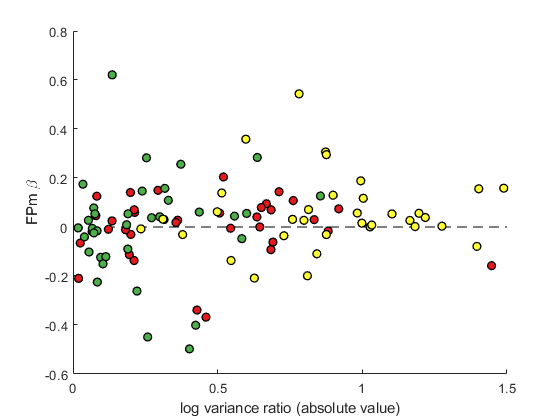

region = 'FPl'

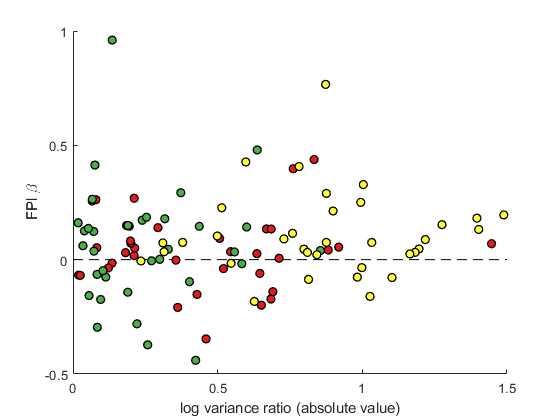

region = 'BA46'

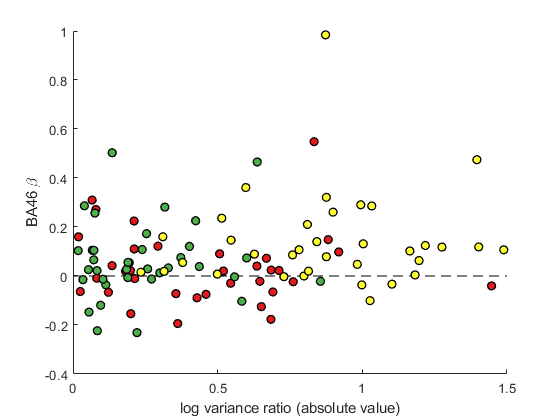

region = 'vmPFC'

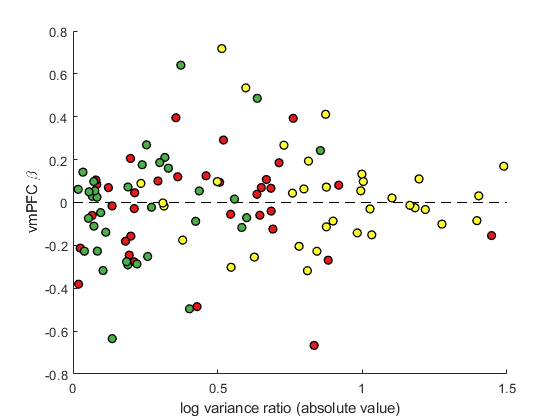

region = 'rSTS'

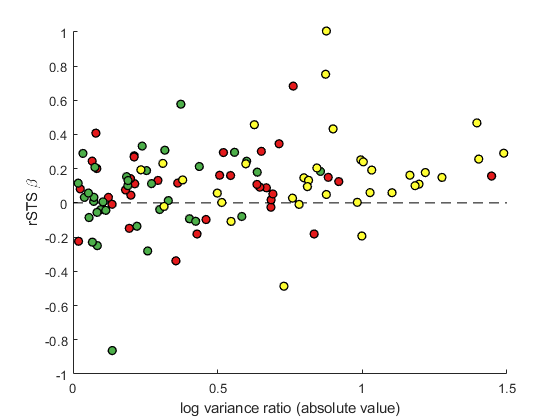

region = 'preSMA'

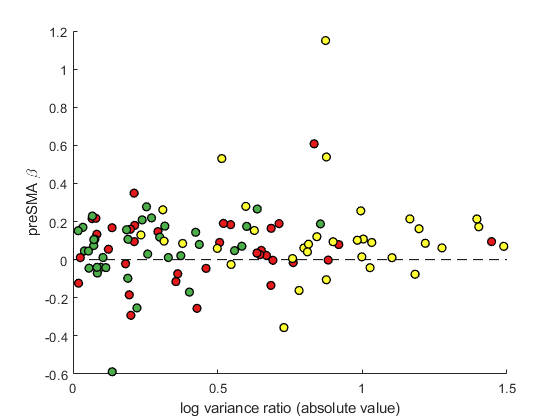

region = 'rTPJ'

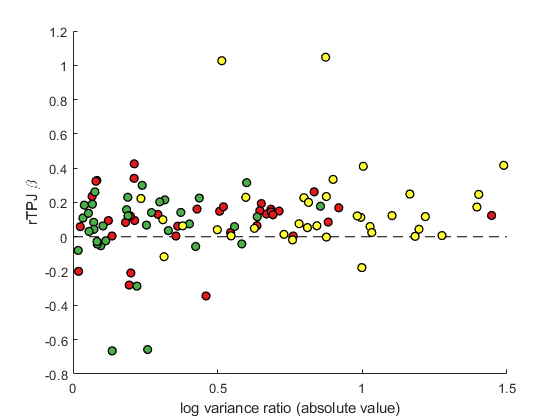

regions = {'FPm','FPl','BA46','vmPFC','rSTS','preSMA','rTPJ'};

for i = 1:length(regions) 
    region = regions{i}
    DetSq = load(fullfile('..','analyzed','DM1555','group','confSqDet',[region,'.mat']));
    DisSq = load(fullfile('..','analyzed','DM1555','group','confSqDis',[region,'.mat']));
    TiltSq = load(fullfile('..','analyzed','DM1555','group','confSqTilt',[region,'.mat']));
    fig=figure; hold on;
    plot([0,1.5],[0,0],'k--')
    % plot([abs(log2(DisSlopes(which_subjects))), ...
    %     abs(log2(DetSlopes(which_subjects))), ...
    %     abs(log2(TiltSlopes(which_subjects)))]', ...
    %     [DisSq.ROI_vec, DetSq.ROI_vec, TiltSq.ROI_vec]', 'k');
    scatter(abs(log2(DetSlopes(which_subjects))),DetSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
    scatter(abs(log2(DisSlopes(which_subjects))),DisSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
    scatter(abs(log2(TiltSlopes(which_subjects))),TiltSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
    xlabel('log variance ratio (absolute value)');
    ylabel([region, ' \beta']);
    hgexport(fig,['figures/slope_ratio_',region],s);
end

regions = {'FPm','FPl','BA46','vmPFC','rSTS','preSMA','rTPJ'};
meanSlopes = mean(abs(log2([DetSlopes DisSlopes TiltSlopes])),2)

meanSlopes =        NaN
    0.3880
    0.7330
    0.4233
       NaN
    0.4688
    1.0817
    0.6258
       NaN
    0.4389


region = 'FPm'

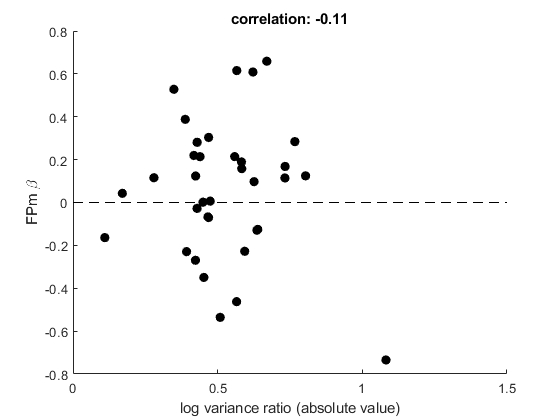

region = 'FPl'

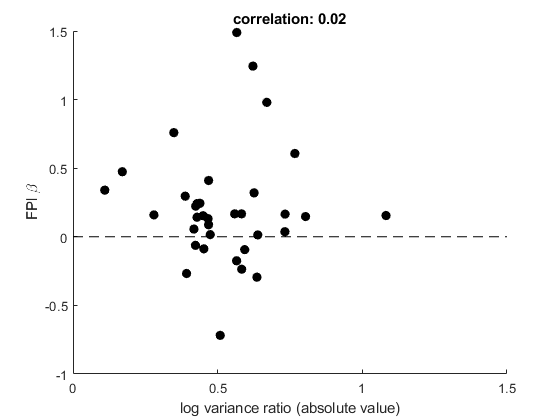

region = 'BA46'

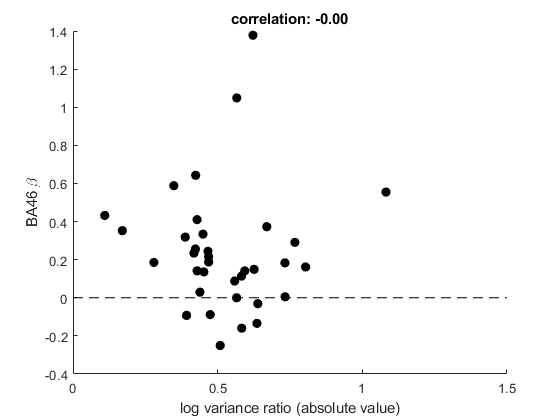

region = 'vmPFC'

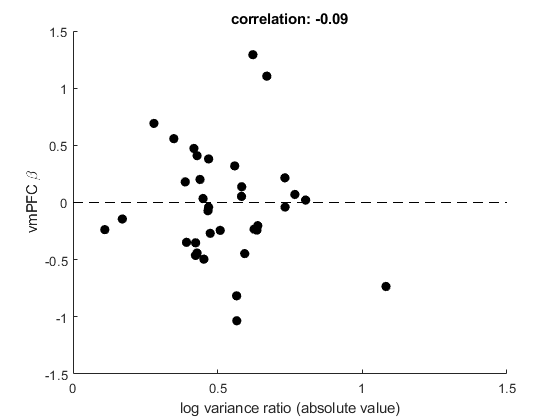

region = 'rSTS'

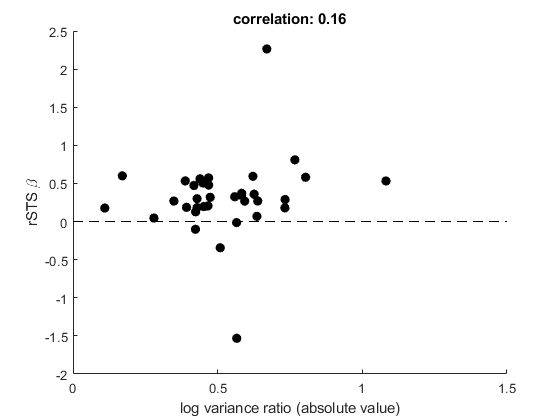

region = 'preSMA'

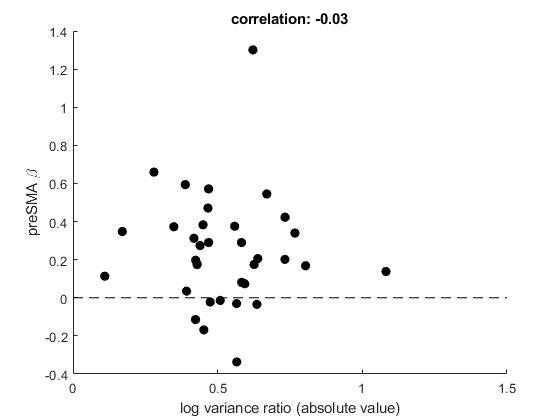

region = 'rTPJ'

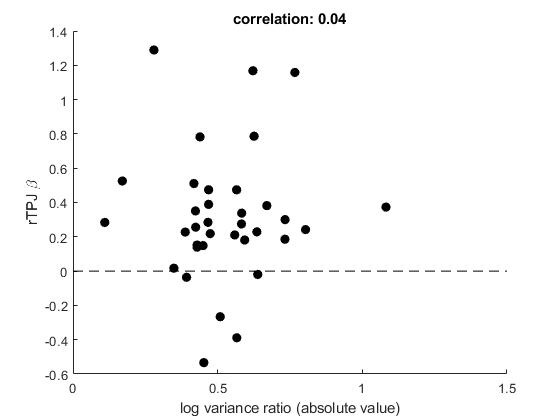

for i = 1:length(regions) 
    region = regions{i}
    Sq = load(fullfile('..','analyzed','DM1555','group','confSq',[region,'.mat']));
    fig=figure; hold on;
    plot([0,1.5],[0,0],'k--')
    % plot([abs(log2(DisSlopes(which_subjects))), ...
    %     abs(log2(DetSlopes(which_subjects))), ...
    %     abs(log2(TiltSlopes(which_subjects)))]', ...
    %     [DisSq.ROI_vec, DetSq.ROI_vec, TiltSq.ROI_vec]', 'k');
    scatter(meanSlopes(which_subjects),Sq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
    title(sprintf('correlation: %0.2f',corr(meanSlopes(which_subjects),Sq.ROI_vec)));

%     scatter(abs(log2(DisSlopes(which_subjects))),DisSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
%     scatter(abs(log2(TiltSlopes(which_subjects))),TiltSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
    xlabel('log variance ratio (absolute value)');
    ylabel([region, ' \beta']);
    hgexport(fig,['figures/mean_slope_ratio_',region],s);
end

Fit mixed linear model

s = nominal(repmat((1:35)',3,1));
task = nominal(repelem((1:3)',35,1));
slope = [DisSlopes(which_subjects); DetSlopes(which_subjects); TiltSlopes(which_subjects)];
ps = [];
for i = 1:length(regions) 
    region = regions{i}
    DetSq = load(fullfile('..','analyzed','DM1555','group','confSqDet',[region,'.mat']));
    DisSq = load(fullfile('..','analyzed','DM1555','group','confSqDis',[region,'.mat']));
    TiltSq = load(fullfile('..','analyzed','DM1555','group','confSqTilt',[region,'.mat']));
    beta = [DisSq.ROI_vec; DetSq.ROI_vec; TiltSq.ROI_vec];

    tbl = table(s,task,slope,beta,'VariableNames',{'s','task','slope','beta'});
    lme = fitlme(tbl,'beta~slope+(1|s)+(slope-1|s)');
    ps(end+1) = lme.coefTest;
end

region = 'FPm'

region = 'FPl'

region = 'BA46'

region = 'vmPFC'

region = 'rSTS'

region = 'preSMA'

region = 'rTPJ'